# Welding poses

A Unimation Puma 560 robot is used to weld a folded tubes frame as it is shown in the next figures.

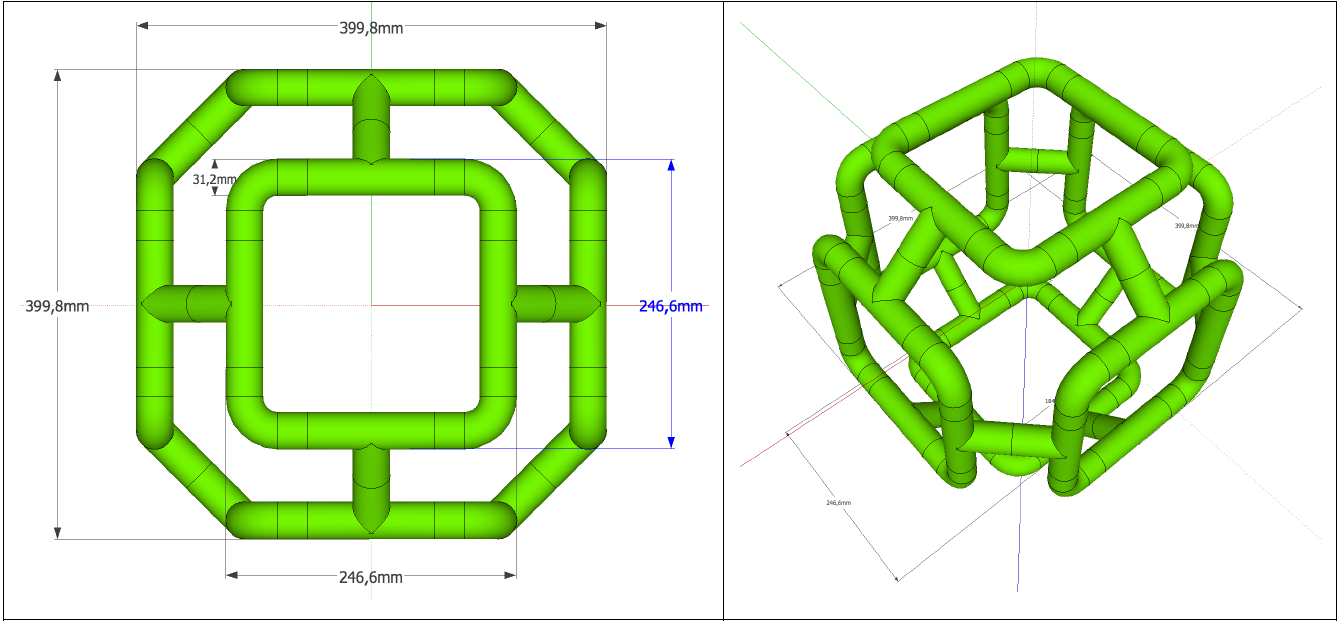

The task for the Puma 560 consists in welding the six folded squared tube among them with 32 points. The welding trajectory can be assumed to as two orthogonal and intersecting cylinders with radius 𝑟 = 15.6mm. The trajectory to be followed by the welder can be parameterized as follows:

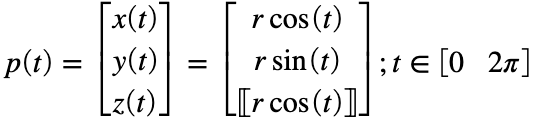

## Read and plot the part

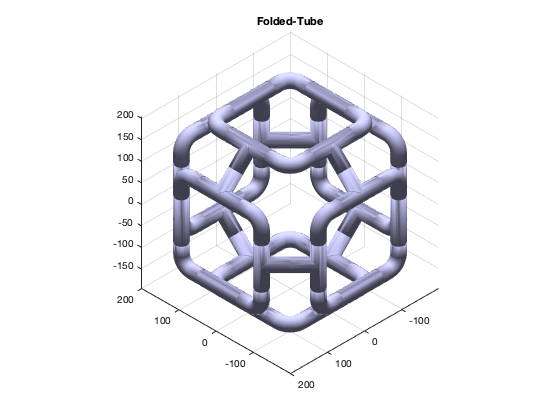

clear
[V,F, N,name]=stlRead('Folded_Tubes.stl');
clf
stlPlot(V,F,name)
axis equal
hold on

## Setting up dimensions

r=15.6; % Tube radius
t=0:pi/16:2*pi; % Scan variable
cp0=[r*cos(t);r*sin(t);abs(r*cos(t));ones(1,length(t))]% dot height

cp0 =    15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000   -3.0434   -5.9699   -8.6669  -11.0309  -12.9709  -14.4125  -15.3003  -15.6000  -15.3003  -14.4125  -12.9709  -11.0309   -8.6669   -5.9699   -3.0434   -0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000
         0    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000   -3.0434   -5.9699   -8.6669  -11.0309  -12.9709  -14.4125  -15.3003  -15.6000  -15.3003  -14.4125  -12.9709  -11.0309   -8.6669   -5.9699   -3.0434   -0.0000
   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000   15.3003   14.4125   12.9709   11.0309    8.6669    5.9699    3.0434    0.0000    3.0434    5.9699    8.6669   11.0309   12.9709   14.4125   15.3003   15.6000
 

## Plotting the welding points at origen

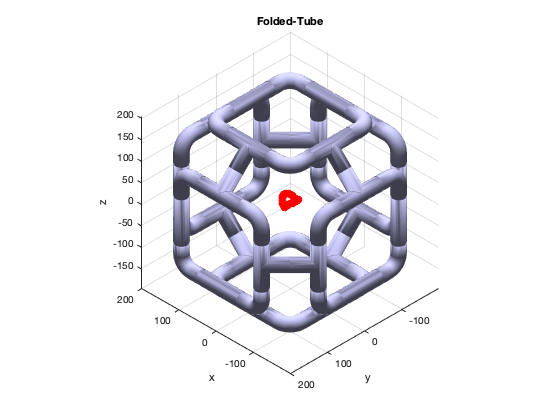

scatter3(cp0(1,:),cp0(2,:),cp0(3,:),'r','LineWidth',2)
xyzlabel

**Obtain the weld point coordinates of two tubes**

Get familiar with the following RTB functions:

help on: transl, trotx, troty, trotz

T = transl(123.3-r, 0, 199.9-r) * troty(90,'deg') * trotz(90, 'deg');
A = T * cp0;

## All weldding points in a vector

Obtain a vector with all weldding points, i.e the six folded squared. Take advantage of the figure symetry.

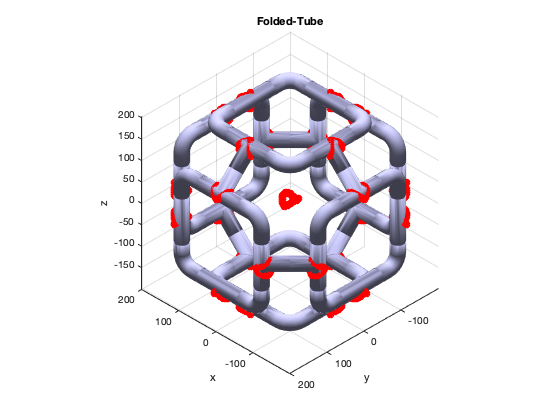

B = trotz(90, 'deg') * A;
C = trotz(180, 'deg') * A;
D = trotz(270, 'deg') * A;
face = [A, B, C, D];

E = trotx(90, 'deg') * face;
F = trotx(180, 'deg') * face;
G = trotx(270, 'deg') * face;
H = troty(90, 'deg') * face;
I = troty(270, 'deg') * face;

Vector = [face, E, F, G, H, I];

scatter3(Vector(1,:), Vector(2,:), Vector(3,:), 'r', 'LineWidth', 2)